# Newton Raphson Method

function NewtonRapshonMethod(f,tol)
    syms x
    x0=1; % Initial condition
    fdx=inf;
    while abs(fdx)>tol
        fdx=subs(diff(f,x),x0); % First derivative of the function at x= x0
        fd2x=subs(diff(f,x,2),x0); % Second derivative of the function at x= x0
        xn=x0-fdx/fd2x; % Newton's Method formula
        x0=xn;
    end
    fx=f(xn);
    fprintf("The minimum value of the function is %.3f at x=%.3f",fx,xn)
end
tol = 10^-3; %default tolerance

## qn1.

tol = 0.0001; 
f = @(x) x.^2 + 54./x;
NewtonRapshonMethod(f, tol);

The minimum value of the function is 27.000 at x=3.000

## qn2.

tol = 0.001;
f = @(x) -3*x.^3.*sin(2*x) + 4*x.*cos(3*x) + 2*x + 4;
NewtonRapshonMethod(f, tol);

The minimum value of the function is 

## Qn3

tol = 0.00001;
f = @(x) x.^3.*cos(2*x) + exp(x);
NewtonRapshonMethod(f, tol);

The minimum value of the function is 2.309 at x=0.960

## Qn4

tol = 0.00001;
f = @(x) 2*x.^2 + 16./x;
NewtonRapshonMethod(f, tol);

The minimum value of the function is 15.119 at x=1.587

## Qn5

tol = 0.00001;
f = @(x) x.^5 - 5*x.^3 - 20*x + 5;
NewtonRapshonMethod(f, tol);

The minimum value of the function is 53.000 at x=-2.000

## Qn6

tol = 0.01;
f = @(x) -4*x.^3 + 100 + exp(x);
NewtonRapshonMethod(f, tol);

The minimum value of the function is 101.248 at x=0.343

## Qn7

tol = 0.00001;
f = @(x) exp(x) - 2*x;
NewtonRapshonMethod(f, tol);

The minimum value of the function is 0.614 at x=0.693

## Qn8

tol = 0.0001;
f = @(x) 1./(x+1) + x.^2;
NewtonRapshonMethod(f, tol);

The minimum value of the function is 0.859 at x=0.297

## Secant Method

function BisectionMethod(f,a,b,tol)
% f is the function to minimize, a and b are intervals, tol is tolerance
    syms x x1 x2
    fda=double(subs(diff(f,x),x,a)); % first derivative of the function at x=a
    fdb=double(subs(diff(f,x),x,b)); % first derivative of the function at x=b
    %Check if the interval is valid
    if fda<0 && fdb>0
        x1=a;
        x2=b;
    elseif fda>0 && fdb<0
        x1=b;
        x2=a;
    else
        fprintf("Invalid interval")
    end
    fdz=inf;
    while abs(fdz)>tol
        z=(x1+x2)/2; % Evaluate z
        fdz=double(subs(diff(f,x),x,z));
        if fdz<0
            x1=z;
        else
            x2=z;
        end
    end
    f_minimum=f(z);
    fprintf("Minimum value of the function is %.3f at x= %.3f",f_minimum,z);
    x_values = linspace(a, b, 1000);
    y_values = f(x_values);
    figure;
    plot(x_values, y_values, 'DisplayName', func2str (f));
    xlabel('x', 'FontWeight', 'bold');
    ylabel('f(x)', 'FontWeight', 'bold');
    grid on;
    title('Secant Method', 'FontWeight', 'bold');
    hold on;
    scatter(z,f_minimum, 'red', 'filled', 'DisplayName', 'Approximate Minimum Point');
    legend('Location', 'Best');
end

## qn1.

Minimum value of the function is 27.000 at x= 3.000

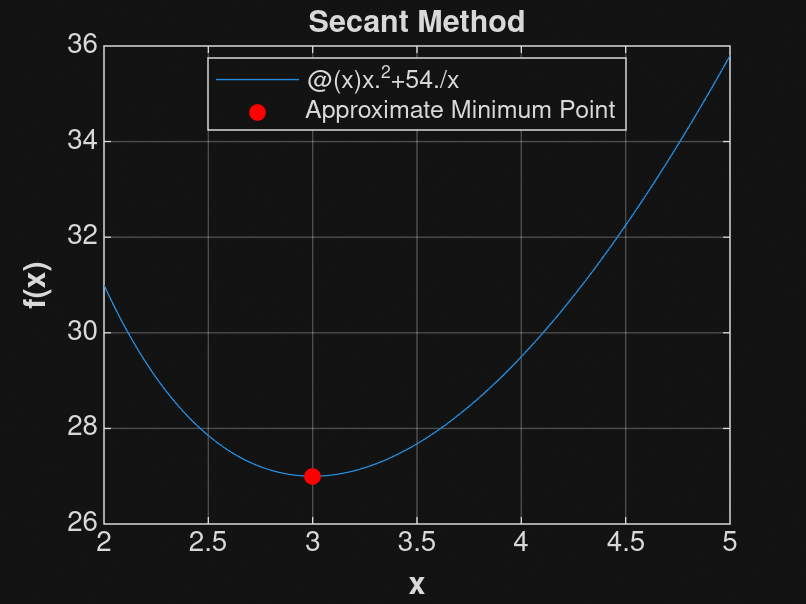

%% qn1
f = @(x) x.^2 + 54./x;
tol = 0.0001;
BisectionMethod(f, 2, 5, tol);

## qn2

Minimum value of the function is -166.669 at x= 4.078

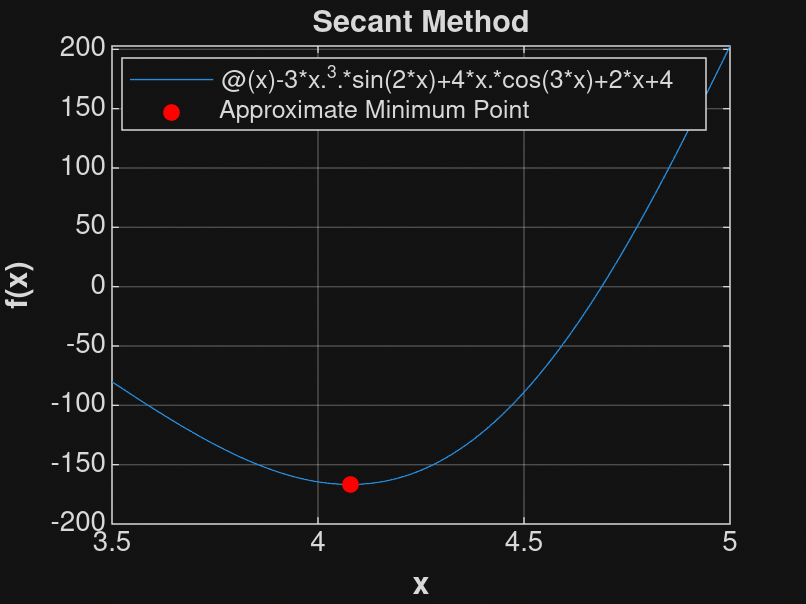

f = @(x) -3*x.^3.*sin(2*x) + 4*x.*cos(3*x) + 2*x + 4;
tol = 0.00001;
BisectionMethod(f, 3.5, 5, tol);

## qn3

Minimum value of the function is 4.555 at x= 4.614

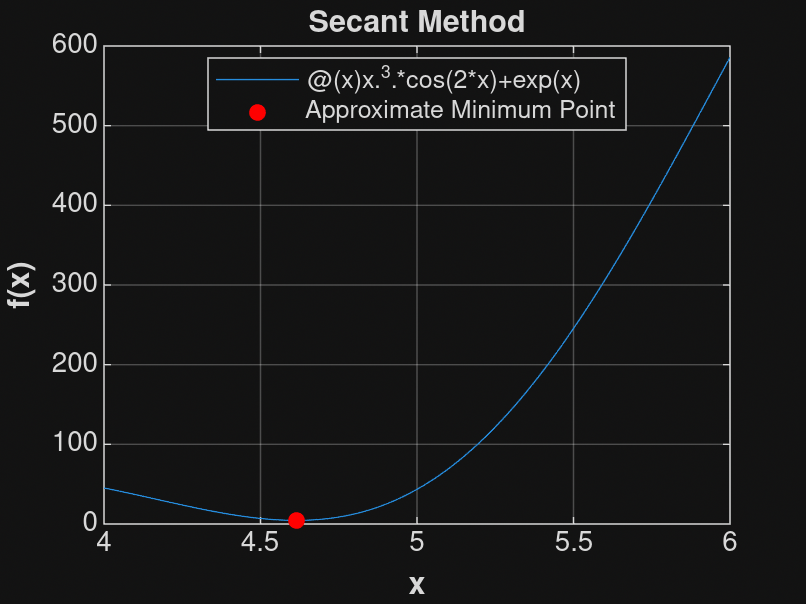

f = @(x) x.^3.*cos(2*x) + exp(x);
tol = 0.00001;
BisectionMethod(f, 4, 6, tol);

## qn4

Minimum value of the function is 15.119 at x= 1.587

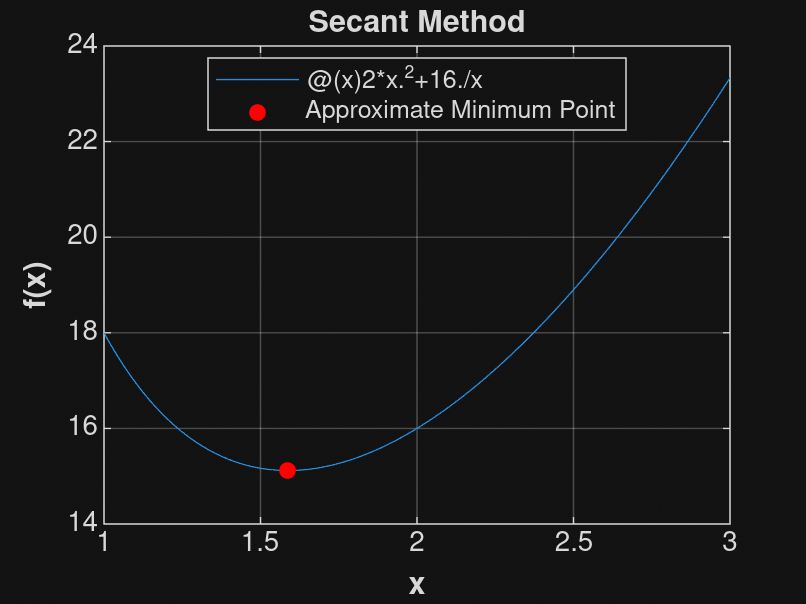

f = @(x) 2*x.^2 + 16./x;
tol = 0.000001;
BisectionMethod(f, 1, 3, tol);

## qn5

Minimum value of the function is -43.000 at x= 2.000

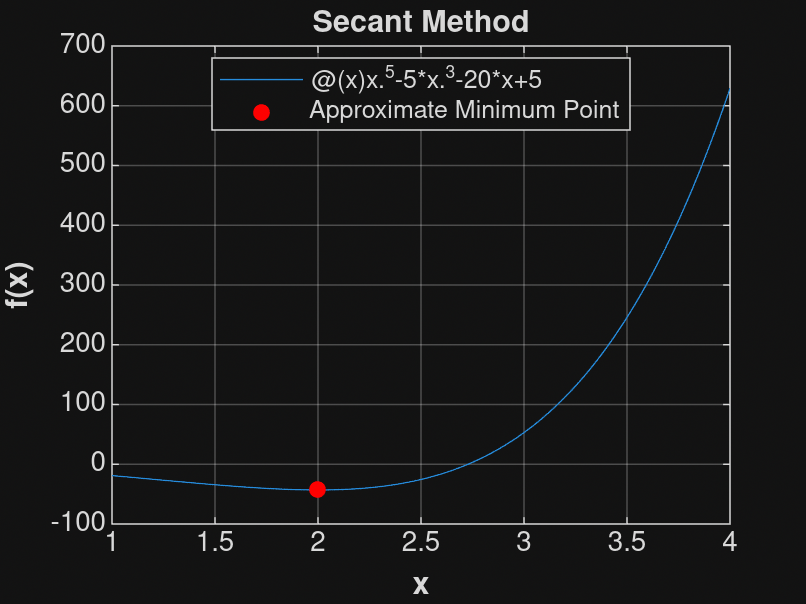

f = @(x) x.^5 - 5*x.^3 - 20*x + 5;
tol = 0.00001;
BisectionMethod(f, 1, 4, tol);

## qn6

Minimum value of the function is -362.067 at x= 6.102

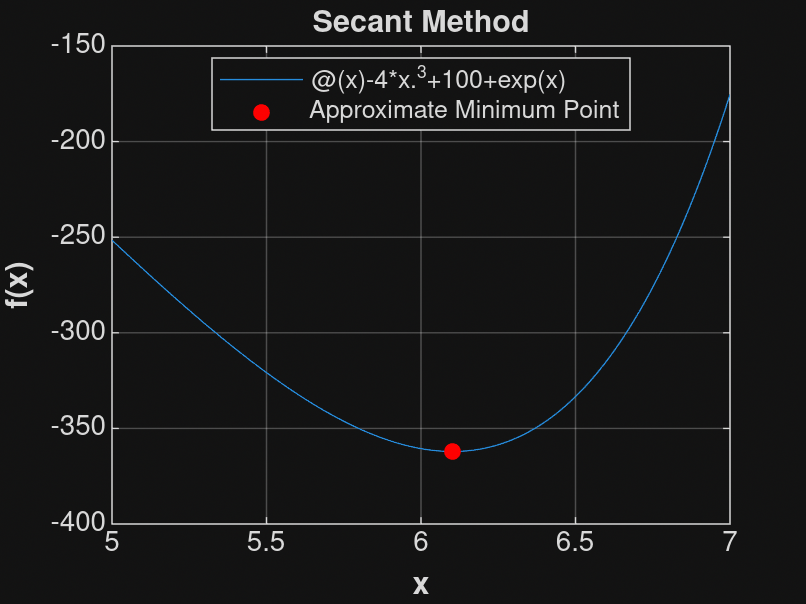

f = @(x) -4*x.^3 + 100 + exp(x);
tol = 0.01;
BisectionMethod(f, 5, 7, tol);

## qn7

Minimum value of the function is 0.614 at x= 0.693

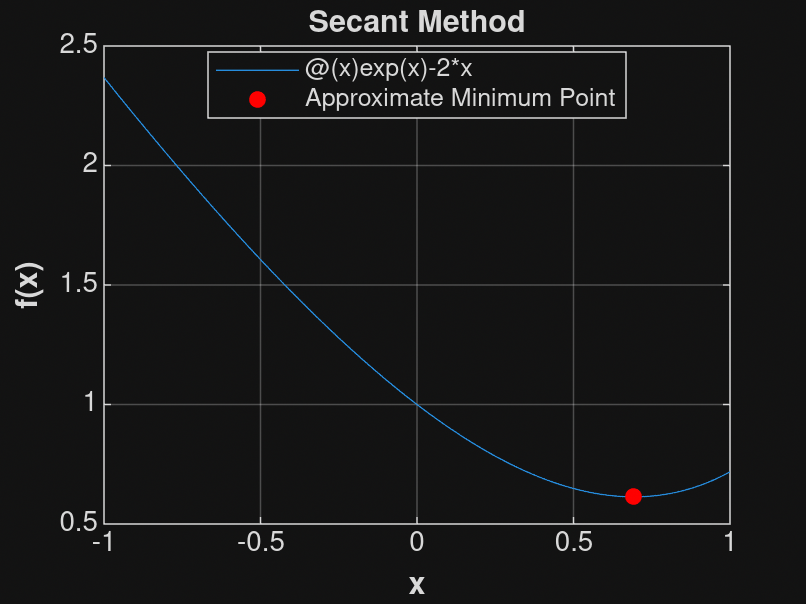

f = @(x) exp(x) - 2*x;
tol = 0.0001;
BisectionMethod(f, -1, 1, tol);

## qn8

Minimum value of the function is 0.859 at x= 0.297

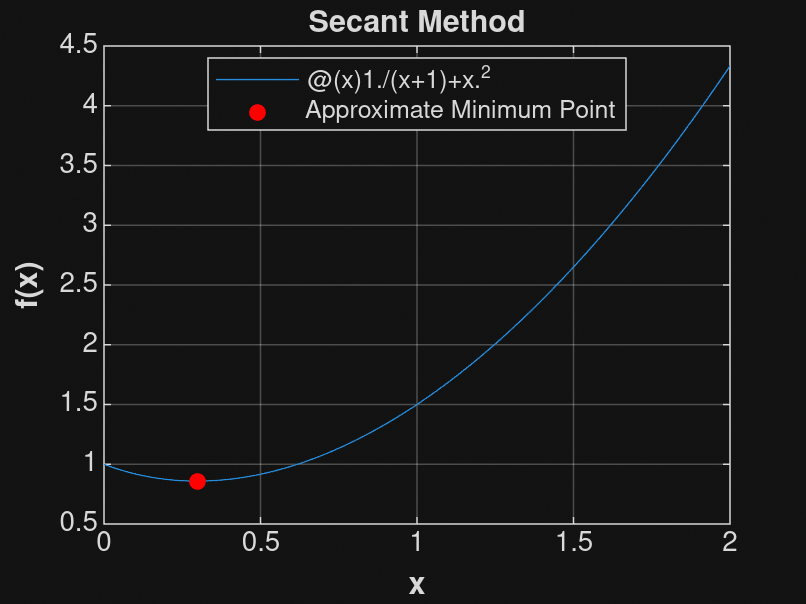

f = @(x) 1./(x+1) + x.^2;
tol = 0.0001;
BisectionMethod(f, 0, 2, tol);